path = char("H:\data\LE14\LE14_231119");
ops = CodeJeff.BuildOps(path);
rawData = CodeJeff.BuildRawData(ops);

Only amplifier & digitalin file names are specified.
Load RawData for the second time.


backslashIdx = strfind(path, '\');
nameBase = path(backslashIdx(end)+1: end);

nameLoad = [nameBase, '_data_base.mat'];
load(fullfile('C:\Users\412\Downloads', nameLoad), 'digTrig', 'spikesHippo', 'spikes');
spk = spikes{1};

spk = spk.CorrectTrigger(digTrig(1));

Error using SpikeData/CorrectTrigger
A trigger already exist. A second one can not be accepted.

nameLoad = [nameBase, '_tracks_forced.mat'];
load(fullfile('C:\Users\412\Downloads', nameLoad), 'tracksForc');
track = tracksForc{ops.forcSeg(1)};
clear tracksForc

nameLoad = [nameBase, '_rate_map_forced.mat'];
load(fullfile('C:\Users\412\Downloads', nameLoad), 'rateMapLI', ...
    'rateMapLO', 'rateMapRO', 'rateMapRI', 'tplIdxLI', 'tplIdxLO', ...
    'tplIdxRO', 'tplIdxRI');

frameRangeTrack = [1 60*ops.frameRate];
timeRange = (frameRangeTrack-ops.forcTrigFrame(1))/ops.frameRate;

win = 0.3;
step = 0.1;
[likelihood, probability, maxPos, timePoints] = PlaceCell.BayesianDecode(spk, ...
    track.positionBins1D(1: 39), rateMapLI, timeRange, win, step);

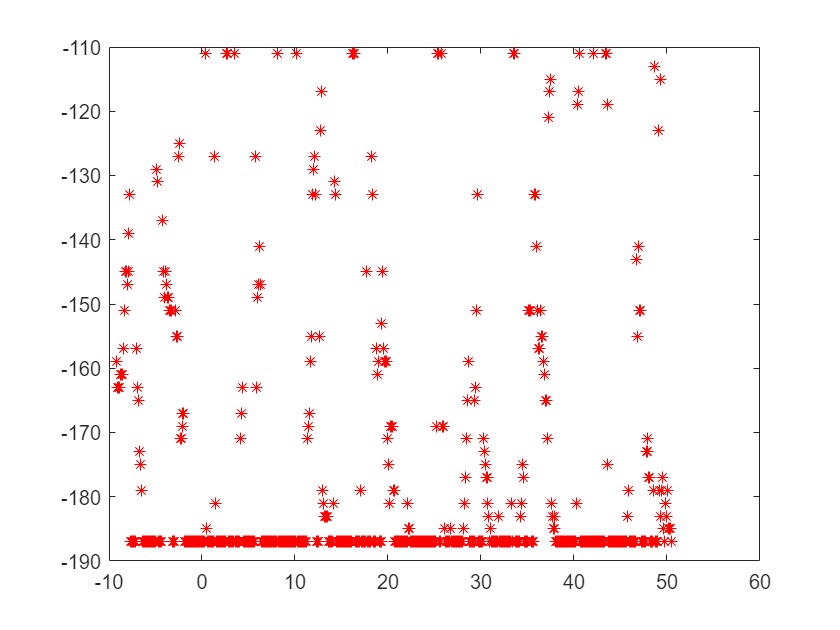

figure
plot(timePoints, maxPos, 'r*');
hold on

timePointsTrack = (frameRangeTrack(1): frameRangeTrack(2)) / track.frameRate;
positionTrack = track.

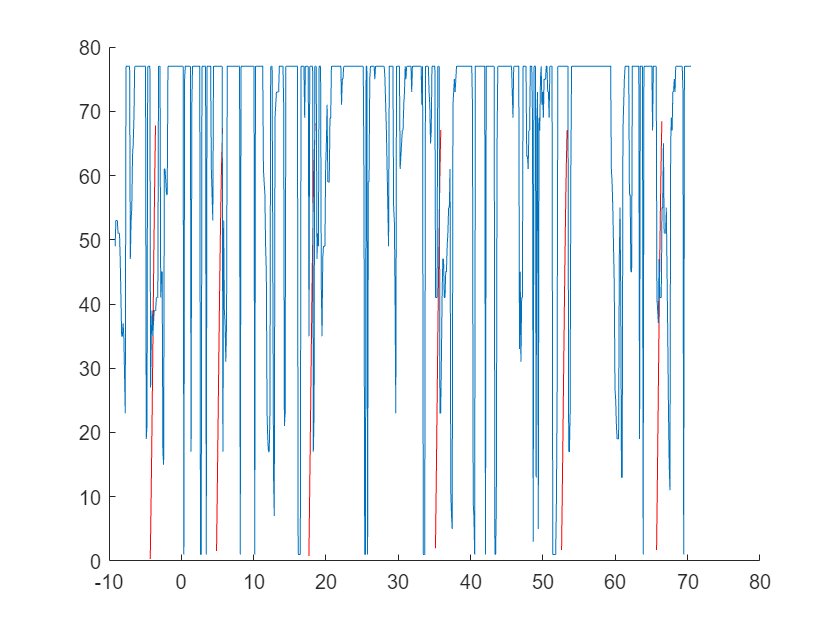

timeRangeAb = [0 60];
timeRangeTrack = timeRangeAb+ops.forcTrigFrame(1)/ops.frameRate;
frameRangeTrack = round(timeRangeAb*ops.frameRate + ops.forcTrigFrame(1));

frame = [1 2400];
timeAb = (frame-ops.forcTrigFrame(1))/30;
timeEphys = timeAb+digTrig(ops.forcTrigOrder(1))/20000;

frameSeries = (frameRange(1): frameRange(2))';

figure
hold on
% tiledlayout(5, 1);
% nexttile
xTrack = (frameSeries-ops.forcTrigFrame(1))/30;
line(xTrack, track.trackProj(frameSeries,1)*track.pixelToCmRatio, 'color', 'r');
% decoder
win = 0.001 * 300;  % 300
step = 0.001 * 100;  % 100
posBinLI = flip(((1: 39) - 0.5)' * ops.binLength);
posBinLO = ((1: 55) - 0.5)' * ops.binLength;
posBinRO = ((1: 55) - 0.5)' * ops.binLength;
posBinRI = ((1: 39) - 0.5)' * ops.binLength;
[~, ~, maxPos, timePt] = PlaceCell.BayesianDecode_v2(spikesHippo, posBinLI, ...
    rateMapLI, timeEphys, win, step);
xEphys = timePt - digTrig(ops.forcTrigOrder(1))/ops.ampSampleRate;
line(xEphys, maxPos);

function PlotTrack(frameSeries)
%% simply plot projected 1d linear track
% prepare
yLimCentral = [0 34*2];
yLimTurn = [0 21*2];
yLimReturn = [0 39*2];
xLimTime = [min(track.frameSeries)/track.frameRate max(track.frameSeries)/track.frameRate];

% plot
figure
hold on
tiledlayout(5, 1);
% central arm
nexttile
plot(track.frameSeries/track.frameRate, track.trackProj(:,1)*track.pixelToCmRatio);
xlim(xLimTime)
ylim(yLimCentral)
title("central arm")
xlabel("time")
ylabel("position")
set(gca, 'xtick', []);
set(gca, 'ytick', []);
% left turn
nexttile
plot(track.frameSeries/track.frameRate, track.trackProj(:,2)*track.pixelToCmRatio)
xlim(xLimTime)
ylim(yLimTurn)
title("left turn")
xlabel("time")
ylabel("position")
set(gca, 'xtick', []);
set(gca, 'ytick', []);
% right turn
nexttile
plot(track.frameSeries/track.frameRate, track.trackProj(:,3)*track.pixelToCmRatio)
xlim(xLimTime)
ylim(yLimTurn)
title("right turn")
xlabel("time")
ylabel("position")
set(gca, 'xtick', []);
set(gca, 'ytick', []);
% left return
nexttile
plot(track.frameSeries/track.frameRate, track.trackProj(:,4)*track.pixelToCmRatio)
xlim(xLimTime)
ylim(yLimReturn)
title("left return")
xlabel("time")
ylabel("position")
set(gca, 'xtick', []);
set(gca, 'ytick', []);
% right return
nexttile
plot(track.frameSeries/track.frameRate, track.trackProj(:,5)*track.pixelToCmRatio)
xlim(xLimTime)
ylim(yLimReturn)
title("right return")
xlabel("time")
ylabel("position")
set(gca, 'xtick', []);
set(gca, 'ytick', []);
end